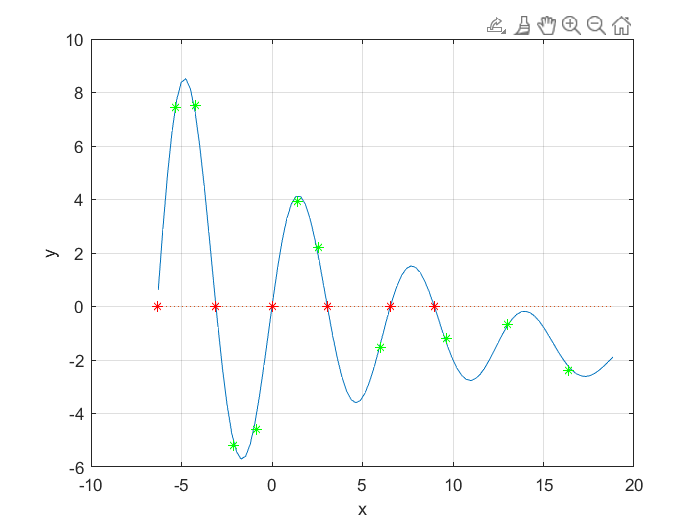

x=linspace(-2*pi,6*pi,100);
f='5*exp(-0.1*x).*sin(x)-0.1*x';
plot(x,eval(f),x,0*x,':');
grid on;
xlabel('x');
ylabel('y');
hold on
for i=1.0:1.0:10.0
    z=ginput(1);
    [zr,fr]=fzero(f,z(1));
    plot(zr,fr,'r*',z(1),z(2),'*g');
end
hold off;